# **WM9QE: Applied Statistics for Artificial Intelligence**

**Seminar: Introduction to MATLAB Programming  **

This seminar is designed to give a practical introduction to MATLAB programming. We will focus on the essential skills needed to write, run, and understand MATLAB code:

- Navigating the MATLAB environment.

- Working with variables, vectors, and basic data types.

- Using MATLAB built-in functions, IF statements and FOR loops to control program logic.

- Creating plots to visualize data.

- Handling tables and simple datasets.

Each section includes short explanations and hands-on examples that you can run and modify. The goal is to build a clear foundation in MATLAB programming that you can apply in future coursework and projects.. 

Useful links/references:

- [Moodle Page: Week One | WM9QE:Applied Statistics for Artificial Intelligence](https://moodle.warwick.ac.uk/course/section.php?id=576666)

- [GitHub Repository](https://github.com/LeonardooAlves/WM9QE-ASAI/)

# Section 1: Introduction to MATLAB Environment

Please Follow the slides for Seminar 1 for an introduction to the MATLAB environment. 

It is always good to clear the command window and saved data before starting a new code, else it will use the previous data and rewrite on some of them, which might result in errors and wrong results. To do so, we can use `clc, clf `and `clear` functions.

- `clc` clears all the text from the Command Window, resulting in a clear screen. 

- `clf` clears current figures

- `clear` removes all variables from the current workspace, releasing them from system memory.

clc; clear; clf;

Summary of useful commands for keeping your MATLAB clean. 

# Section 2: Data Types and Variables

## 2.1 Variables and Vectors

In MATLAB, you create variables by assignment. Let's create some data.

A single number (scalar)


$$a=-5\ldotp 12345$$


a = -5.12345

a =       -5.1235


Absolute_a = abs(a) % abs(x) returns the absolute value of each element in input X.

Absolute_a =        5.1235


Round_a =  round(a,1)             % Y = round(X,N) rounds to N digits: 

Round_a =          -5.1


                        % N > 0: round to N digits to the right of the decimal point.
                        % N = 0: round to the nearest integer.
                        % N < 0: round to N digits to the left of the decimal point.

**Important Note: MATLAB is Case-Sensitive. **Variable names, function names, and commands must match the exact capitalization.

Ac = 10;
ac = 5;

Ac  % Outputs 10

Ac =     10


ac  % Outputs 5

ac =      5


A row vector:


$$b=\left\lbrack \begin{array}{ccccc}
1 & 2 & 3 & 4 & 5
\end{array}\right\rbrack$$


% A row vector
 b = [1 2 3 4 5]

b =      1     2     3     4     5


A column vector:


$$c=\left\lbrack \begin{array}{c}
10\\
20\\
30\\
40\\
50
\end{array}\right\rbrack$$


 c = [10;20;30;40;50]

c =     10
    20
    30
    40
    50


A matrix (2D array):


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


 A = [1 2 3;4 5 6;7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


Gettign information of the matrix/array:

A_Dimensions = size(A)          % size(A) dimensions of the Matrix

A_Dimensions =      3     3


A_2  = A(2,1)                 % A(2,1) element access (number of row, number of column)

A_2 =      4


A_Second_Column = A(:,2)     % A(:,2) using : you can get all the elements on the 2nd Column 

A_Second_Column =      2
     5
     8


A_Third_Row  = A(3,:)         % A(3,:) getting all the elements on the 3rd row

A_Third_Row =      7     8     9


L_A     = length(A)               % length(A) Returns the length of the largest array dimension. For vectors, the length is simply the number of elements. For arrays with more dimensions, the length is max(size(T)). The length of an empty array is zero.

L_A =      3


You can create array of all ones using `ones` function.

C = ones(3)        % ones(n) returns an n-by-n matrix of ones.

C =      1     1     1
     1     1     1
     1     1     1


D = ones(2,3)      % ones(2,3) returns a 2-by-3 array of ones.

D =      1     1     1
     1     1     1


`linspace` creates linearly spaced vectors.

% Syntax: v = linspace(start, end, numPoints)

% Create 5 points between 0 and 10
v = linspace(0, 10, 5);

% Display the result
disp('Linearly spaced vector:')

Linearly spaced vector:


disp(v)

            0          2.5            5          7.5           10



The function `repmat(A, m, n)` creates a large array by **replicating array **`A` in a tiling pattern:

- `m` = number of times to repeat in **rows**

- `n` = number of times to repeat in **columns**

% Replicating a row vector
Z = [1 2 3];

% Repeat it into a 4x3 matrix
Z_rep = repmat(Z, 4, 1);

disp("Row vector repeated 4 times:")

Row vector repeated 4 times:


disp(Z_rep)

     1     2     3
     1     2     3
     1     2     3
     1     2     3




% Replicating any character 
repmat('-',1,50)

ans = '--------------------------------------------------'

Function `arrayfun` applies a function to each element of an array without writing an explicit loop. 

Think of it as "a for-loop in one line."

**Syntax**: `B = arrayfun(@(x) func(x), A)`

Where: 

- A is the input array

- func(x) is the operation applied to each element, it can be anything, even `plot` 

- B is the resulting array

% Input array
A_fun = [1, 2, 3, 4, 5]

A_fun =      1     2     3     4     5



% Apply function (square each element)
B_fun = arrayfun(@(x) x^2, A_fun)

B_fun =      1     4     9    16    25


## 2.2 Generate Random Numbers 

Random numbers are very important in **AI, data science, and simulations** (e.g., random initialization of model weights, random sampling of data, or generating synthetic datasets). There are different MATLAB in-built functions for that including:

- `rand` generates random numbers between **0 and 1**. You can specify the size of the array.

- `randsample` randomly selects elements from a set. Useful for **data sampling, train-test splits, or bootstrapping**.

K = rand(4,5)           % rand(n) returns an n-by-n matrix of uniformly distributed random numbers.

K =       0.46078      0.69039     0.081759      0.27688      0.20935
      0.20633     0.039312      0.87358       0.8062      0.37047
      0.36427      0.79941      0.92087      0.74826      0.48452
      0.50342       0.6279     0.061078      0.18452      0.61825


L = randn(4,5)          % randn(n) returns normally distributed random numbers

L =      -0.41866     -0.42293     0.031307     -0.39745     -0.81303
     -0.14705       0.8049      -1.8705     -0.92217     -0.41866
      0.31284       1.8162     -0.13534     -0.23612     -0.55331
     -0.81787      0.04731     0.088781      -1.5863     -0.81063


N = randi([-5,5],10,1)  % randi generates uniformly distributed random integers. For isntance this example generate a 10-by-1 column vector of uniformly distributed random integers from the sample interval [-5,5]

N =      4
     1
     2
     3
     0
    -5
     0
     1
     3
    -1


Random_S = randsample(10,4)    % randsample(n,k) returns k values sampled uniformly at random, without replacement, from the integers 1 to n.

Random_S =     10
     1
     9
     2


**Control Randomness:** Random numbers in MATLAB come from a **random number generator (RNG)**. If you don’t control it, results may differ each time you run the code.

- `rng(seed)` sets the seed, so results are **reproducible**.

- `rng default` resets MATLAB’s random generator to its default settings. Useful when you want **consistent, repeatable results** across sessions.

So it would be good to set the rng as default and include a fixed seed after that. 

rng("default")       % initializes the MATLAB® random number generator using the default algorithm and seed. 
rng(42)

## 2.3 Output Display

The **semicolon** symbol (`;`) suppresses output of a single command, separates multiple commands on the same line while suppressing output, and also denotes the end of a row when creating an array. For instnace, if you define a new variable and this time put semicolon at the end of your code you will not see the results:

d=55;

This comes handy when you have a long code and you only wnat to display specific results at the end. 

`disp(`[`X`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/disp.html?searchHighlight=disp&s_tid=doc_srchtitle#btnow0n-1-X)`)` displays the value of variable `X` without printing the variable name. Another way to display a variable is to type its name, which displays a leading “`X =`” before the value. If a variable contains an empty array, `disp` returns without displaying anything.

% Display them
disp('Scalar:')

Scalar:



disp('Vector c:')

Vector c:


disp(c)

    10
    20
    30
    40
    50




disp('Matrix A:')

Matrix A:


disp(A)

     1     2     3
     4     5     6
     7     8     9



To display multiple variable values on the same line, you can convert any numeric values to characters using the `num2str` function. Use `disp` to display the result.

disp(['The results increased ', num2str(d), '%.' ])

The results increased 55%.


You can use `fprintf``(``___``), `which returns the number of bytes that `fprintf` writes, using any of the input arguments in the preceding syntaxes.

`fprintf``(`[`formatSpec`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/fprintf.html?searchHighlight=fprintf&s_tid=doc_srchtitle#btf8xsy-1_sep_shared-formatSpec)`,`[`A1,...,An`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/fprintf.html?searchHighlight=fprintf&s_tid=doc_srchtitle#btf8xsy-1-A1An)`)` formats data and displays the results on the screen.

a = 3.4567;
d = 9.8765;
fprintf('The range of data is from %4.2f to %4.2f.', d, a)

The range of data is from 9.88 to 3.46.

`%4.2f` in the `formatSpec` input specifies that the first value in each line of output is a floating-point number with a field width of four digits, including two digits after the decimal point. 

See [fprintf](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/fprintf.html?searchHighlight=fprintf&s_tid=doc_srchtitle) for full details.

`sprintf` is used to format text as a string. Unlike `fprintf`, it does not print to the command window by default, but instead returns a string that you can store in a variable, display later, or use in plots, tables, or files.

## 2.4 Basic Math Operation 

You can do element-wise operations easily.

b = [2 4]

b =      2     4


e = b + 1;         % Adds 1 to each element of vector b
f = b .* b;        % Element-wise multiplication
g = sum(b);        % Sum of all elements

disp(['Sum of b = ', num2str(g)])

Sum of b = 6


MATLAB has built-in functions for statistical analysis, let's see an example:

mean_b = mean(b);       % Average (mean)
std_b = std(b);        % Standard deviation
var_b = var(b);        % Variance
median_b = median(b)      % Median

median_b =      3


% 
disp(['Mean of b = ', num2str(mean_b)])

Mean of b = 3


Let's use the functions for statistical analysis in another example:

sample = [12, 15, 14, 10, 9, 13, 15, 16];

% Common statistics
meanVal = mean(sample);        % Returns the mean of the data samples 
medianVal = median(sample);    % Returns the median of the data samples
stdVal = std(sample);          % Returns the standard deviation of the elements 
minVal = min(sample);          % Returns the minimum elements of an array.
maxVal = max(sample);          % Returns the maximum elements of an array.
rangeVal = range(sample);      % Returns the difference between the maximum and minimum values of sample data
iqrVal = iqr(sample);          % Interquartile range
Product_sample= prod(sample)   % prod(A) returns the product of the array elements of A.

Product_sample =    707616000



fprintf('Mean = %.2f, Median = %.2f, Std = %.2f\n', meanVal, medianVal, stdVal)

Mean = 13.00, Median = 13.50, Std = 2.51


fprintf('Min = %.2f, Max = %.2f, Range = %.2f, IQR = %.2f\n', minVal, maxVal, rangeVal, iqrVal)

Min = 9.00, Max = 16.00, Range = 7.00, IQR = 4.00


## 2.5 Data Types

By default, MATLAB stores all numeric variables as **double-precision** floating-point values. “Floating point” refers to a set of data types that encode real numbers, including fractions and decimals. MATLAB has data types for single-precision ([`single`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/single.html)) and double-precision ([`double`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/double.html)).

Single-precision variables are stored as 4-byte (32-bit) and double-precision are stored as 64-bit (8-byte) floating-point values. Double precision allows you to represent numbers to greater precision but requires more memory than single precision.

Additional data types (classes) store text, integer or single-precision values, or a combination of related data in a single variable. For more information, see [Fundamental MATLAB Classes](https://uk.mathworks.com/help/releases/R2024b/matlab/matlab_prog/fundamental-matlab-classes.html). The fundamental MATLAB classes are shown in the diagram.

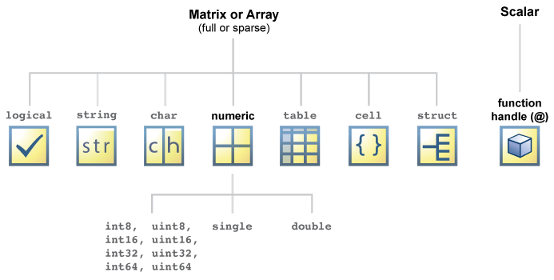

Let's try it on a data:


$$x=5\times {10}^{-100}$$


x=5e-100

x =        5e-100


x_single=single(x) %you might lose some data using Single-precision

x_single = single
     0


x_double=double(x)

x_double =        5e-100


You can see the details of data using `class` and `whos` functions. 

- `class(`[`obj`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/class.html?searchHighlight=class&s_tid=doc_srchtitle#mw_6f09edb1-fdf2-4328-8d55-1607d809b97d)`)` returns the name of the class of `obj`.

- `whos` lists in alphabetical order the names, sizes, and types of all variables in the currently active workspace. `whos [name of var] `lists only the specified variables. 

class(x)

ans = 'double'

whos x_single

  Name          Size            Bytes  Class     Attributes

  x_single      1x1                 4  single              



whos x_double

  Name          Size            Bytes  Class     Attributes

  x_double      1x1                 8  double              



`format(`[`style`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/format.html?searchHighlight=format+long&s_tid=doc_srchtitle#btiwmh5-1-style)`)` changes the output display format to the format specified by `style`. For example, `format``("shortG")` displays numeric values in a compact form with 5 total digits. Numeric formats affect only how numbers appear in the display, not how MATLAB computes or saves them.

y=[25 56.31156 255.52675 9876899999];

format long
y_long=y

y_long = 1.0e+09 *

   0.000000025000000   0.000000056311560   0.000000255526750   9.876899999000001



format short
y_short=y

y_short = 1.0e+09 *

    0.0000    0.0000    0.0000    9.8769



format shortG
y_shortG=y

y_shortG =            25       56.312       255.53   9.8769e+09



%Use the shortG format when some of the values in an array are short numbers and some have large exponents. 
%The shortG format picks whichever short fixed-decimal format or short scientific notation has the most compact display.

format longEng
y_longEng=y

y_longEng =     25.0000000000000e+000    56.3115600000000e+000    255.526750000000e+000    9.87689999900000e+009



format shortEng
y_shortEng=y

y_shortEng =     25.0000e+000    56.3116e+000   255.5267e+000     9.8769e+009


The last `format` that you put in your code will be used for the rest of the programme. So let's assign format shortG for now. 

format shortG


**What is a categorical array?**

`categorical` is a MATLAB data type that assigns values to a finite set of discrete categories, such as *High*, *Med*, and *Low*. Categories can be **unordered** (just names) or **ordered** (e.g., *High > Med > Low*). Categorical arrays provide:

- Efficient storage of nonnumeric data

- Convenient manipulation of groups

- Meaningful names for values instead of arbitrary numbers

A common use is to define groups of rows in a table (e.g., grouping patients by gender or by smoker status). Let's have a look at an excample of creating categorical data with ordering:

% Define levels of risk
riskLevels = {'High','Med','Low','Med','Low','High'};

% Convert to categorical, with ordering High > Med > Low
riskCat = categorical(riskLevels, {'Low','Med','High'}, 'Ordinal',true);

disp('Categorical array:')

Categorical array:


disp(riskCat)

     High      Med      Low      Med      Low      High 




disp('Defined categories (with order):')

Defined categories (with order):


categories(riskCat)        %Returns list of categories in categorical array

ans = 3×1 cell 数组
    {'Low' }
    {'Med' }
    {'High'}


The function `countcats(C)` counts the **number of elements** in each category of a **categorical array**.

- Works only with categorical arrays (not numeric or string arrays directly).

- Can count across rows or columns using a dimension argument.

- Very useful for summarizing categorical data (like class labels in AI).

%% Example 1: Counting categories
animals = categorical(["dog","cat","dog","fish","cat","dog"]);

% Count occurrences of each category
counts = countcats(animals);

disp("Counts of each category:")

Counts of each category:


disp(counts)

     2     3     1




% Show which categories correspond to the counts
disp("Categories:")

Categories:


disp(categories(animals))

    {'cat' }
    {'dog' }
    {'fish'}



**What is a string?**

A **string** is text data, such as `"Hello"` or `"MATLAB"`. In MATLAB, strings are written with **double quotes** `" "` (not single quotes `' '`, which create character arrays). Strings are useful for storing and manipulating text, labels, file names, or categorical information. Let's have a look at an example for string arrays:

cities = ["London", "Paris", "New York", "Tokyo"];

% Access element
disp(cities(2))

Paris



% Count number of characters in each city
strlength(cities)

ans =      6     5     8     5


`string(`[`A`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/string.html?searchHighlight=string&s_tid=doc_srchtitle#d126e1729937)`)` converts the input array to a string array. You use `string(A)` to turn numeric, logical, or categorical data into strings so you can display it, combine with text, or store in a table for labeling.

names = ["Alice", "Bob", "Charlie"]; 
scores = [90, 85, 78];               
P = table(names', scores', 'VariableNames', {'Name', 'Score'});
disp(P)

      Name       Score
    _________    _____

    "Alice"       90  
    "Bob"         85  
    "Charlie"     78  




scores_str = string(scores);  % convert numeric to string
Q = table(names', scores_str', 'VariableNames', {'Name', 'Score'});
disp(Q)

      Name       Score
    _________    _____

    "Alice"      "90" 
    "Bob"        "85" 
    "Charlie"    "78" 



Join strings in array by using `strjoin.`

R = {'one','two','three'};
str_R = strjoin(R)

str_R = 'one two three'

Join the character vectors in a cell array into one character vector. Specify a comma followed by a space character as the delimiter.

S = {'Newton','Gauss','Euclid','Lagrange'};
str_S = strjoin(S,', ')

str_S = 'Newton, Gauss, Euclid, Lagrange'

# Section 3: Making Decisions and Repeating Tasks, IF and FOR Loops

In this section, we learn how to make decisions (IF statements) and repeat tasks (FOR loops). These are essential in AI and Data Science for handling data, building algorithms, and controlling program logic.

## 3.1 Introduction to IF Statements

`If` evaluates an [expression](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/if.html#bt_csfy), and executes a group of statements when the expression is true. An expression is true when its result is nonempty and contains only nonzero elements (logical or real numeric). Otherwise, the expression is false.

% if expression
%     statements
% end
clc; clear; clf;

%Example: Simple IF: display x is greater than 5 if it is. 
x = 7;

if x > 5
   disp("x is larger than 5 ")
end

x is larger than 5 


The `elseif` and `else` blocks are optional. The statements execute only if previous expressions in the `if...end` block are false. An `if` block can include multiple `elseif` blocks.

% if expression
%     statements
% elseif expression
%     statements
% else
%     statements
% end

% Example: IF-ELSE
if x < 5
    disp("x is less than 5")
else
    disp("x is greater or equal to 5")
end

x is greater or equal to 5


% Example IF-ELSEIF-ELSE, display if x is zero, positive or negative. 


## 3.2 Introduction to FOR Loops

A "for" loop allows you to repeat a set of commands a fixed number of times. 

- Loops are very useful in data processing, simulations, and AI workflows. 

- Preallocate arrays for better performance. 

- Loops can contain conditional statements (if/else) for decision-making. 

- Nested loops allow iterating over multiple dimensions.

% Syntax:
%   for index = start:step:end
%       % commands
%   end


**Example Basic Loop: **Print numbers from 1 to 5

clc; clear; clf;

for i = 1:5
    fprintf('Iteration number: %d\n', i); % %d formats i as integer
end

Iteration number: 1
Iteration number: 2
Iteration number: 3
Iteration number: 4
Iteration number: 5



% Explanation:
% - 'i' is the loop index variable.
% - The loop runs from 1 to 5.
% - fprintf prints the output in the Command Window.

**Example Loop through an Array**: Square each element in an array

arr = [2, 4, 6, 8];             % define an array
squared_arr = zeros(size(arr)); % preallocate output array
for i=1:1:length(arr)
    squared_arr(i) = arr(i)^2;
end
disp(squared_arr)

     4    16    36    64



**Example Nested Loops: **Create a multiplication table 1-3 x 1-4

clc; clear; clf;
%Create a multiplication table 1-3 x 1-4 using for loop
for i = 1:3            % 外层循环控制行（1 到 3）
    for j = 1:4        % 内层循环控制列（1 到 4）
        product = i * j;
        fprintf('%2d x %2d = %2d\t', i, j, product);
    end
    fprintf('\n');     % 每行结束后换行
end

 1 x  1 =  1	 1 x  2 =  2	 1 x  3 =  3	 1 x  4 =  4	 2 x  1 =  2	 2 x  2 =  4	 2 x  3 =  6	 2 x  4 =  8	 3 x  1 =  3	 3 x  2 =  6	 3 x  3 =  9	 3 x  4 = 12	

**Example Using Conditional Statements inside a for Loop:** Identify even and odd numbers from 1 to 10

clc; clear; clf;
% Identify even and odd numbers from 1 to 10 using For loop and if
% statement.
% mod(a,m) returns the remainder after division of a by m

for i = 1:10            % 外层循环控制行（1 到 3）
   if mod(i, 2) == 0
        fprintf('%d is even.\n', i);
    else
        fprintf('%d is odd.\n', i);
    end
end

1 is odd.


2 is even.


3 is odd.


4 is even.


5 is odd.


6 is even.


7 is odd.


8 is even.


9 is odd.


10 is even.


## 3.3 Logical Operators

### **3.3.1 Element-wise Logical Operators**

Used when **working with vectors/matrices**. Always evaluates **both sides** of the condition, even if the first part is already false/true.

- `&` = **AND**, checks each element of an array.

- `|` = **OR**, checks each element of an array.

E = [true false true];
F = [false false true];

E & F   % element-wise AND → [false false true]

ans = 1×3 logical 数组
   0   0   1


E | F   % element-wise OR  → [true false true]

ans = 1×3 logical 数组
   1   0   1


### **3.3.2 Short-Circuit Logical Operators**

Useful for efficiency (avoiding unnecessary calculations) and for conditions that might cause errors if both sides are always evaluated.

- `&&` = **short-circuit AND**, used for **scalars only**.

- `||` = **short-circuit OR**, used for **scalars only**.

**Short-circuiting** means:

- In `cond1 && cond2`, if `cond1` is `false`, MATLAB **skips** checking `cond2`.

- In `cond1 || cond2`, if `cond1` is `true`, MATLAB **skips** checking `cond2`.

clc; clear; clf;
% Example for Logical operators: && (AND)
x = 7;
y = 12;

if (x > 5 && y > 10)
    disp("Both conditions are true")
end

Both conditions are true


Let's see and example using short-circuit AND (`&&`):

clc; clear; clf;

x = 5;
y = 0;

if (x > 0) && (y ~= 0 && (x/y) > 1)  
    disp("Condition true")
else
    disp("Condition false")
end

Condition false



% If we used & instead of &&, MATLAB would try to compute (x/y)
% → division by zero error!
% → division by zero error!

You can see the full list  of MATLAB Operators and Special Characters at [MATLAB Operators and Special Characters](https://uk.mathworks.com/help/releases/R2024b/matlab/matlab_prog/matlab-operators-and-special-characters.html#bvg3oy_-3?s_tid=doc_ta).

### 3.3.3 Comparing Data

The function `ismember(A, B)` checks whether the elements of `A` are found in `B`.

- Returns a logical array the same size as `A`.

- Can also return index positions of matches in `B`.

clc; clear; clf;
%% Example 1: Checking membership in a vector
U = [3 5 7 9];
V = [1 3 5 8 9];

% Check which elements of A are in B
W = ismember(U, V);

disp("Logical result: ")

Logical result: 


disp(W)   % [1 1 0 1] → 3, 5, 9 are found in B, but 7 is not

   1   1   0   1




% Use logical indexing to extract common values
common_vals = U(W);
disp("Common values between A and B:")

Common values between A and B:


disp(common_vals)

     3     5     9



You can find the difference between the arrays/tables using `setdiff. `

setdiff(U,V)       % Find the values in K that are not in L.

ans =      7


Filtering a dataset using `ismember.`

Y = table(["Alice";"Bob";"Charlie";"Diana";"Eve"], [25;30;22;29;35], ...
          'VariableNames', {'Name','Age'});

% Suppose we only want rows for Bob and Eve
wanted_names = ["Bob","Eve"];

mask = ismember(Y.Name, wanted_names);

filtered_Y = Y(mask, :);

disp("Filtered table with only Bob and Eve:")

Filtered table with only Bob and Eve:


disp(filtered_Y)

    Name     Age
    _____    ___

    "Bob"    30 
    "Eve"    35 



Tip: If a line of code is too long, you can use `...` (three dots) at the end of a line to **continue it on the next line**. This improves readability and keeps your code consistent.

# Section 4: Plots and Presentation

This section introduces MATLAB’s visualization capabilities, which are essential for applied statistics, AI, and data science. You will learn how to create clear and professional plots to visualize data distributions, relationships, and model results. Well-designed plots allow us to:

- Explore patterns in data 

- Identify anomalies and outliers 

- Communicate findings clearly

**Preparation: Clean the workspace. **This ensures no old variables or figures interfere with our new plots

clearvars;   % Clears all variables from the workspace
close all;   % Closes all open figure windows
clc;         % Clears the command window

## 4.1 Plot Presentation and Details

When making plots, clarity and professionalism are essential. MATLAB plots can be customized with:

- **Titles** → `title("My Plot")`

- **Axis labels** → `xlabel("X Axis"), ylabel("Y Axis")`

- **Legends** → `legend("Series1","Series2")`

- **Gridlines** → `grid on`

- **Colors & markers** → `plot(x,y,'r--o')` (red dashed line with circles)

- **Line width & font size** for clar

### 4.1.1 Basic Line Plot

Line plots are used to visualize the relationship between two continuous variables. Example: Plotting a sine function.

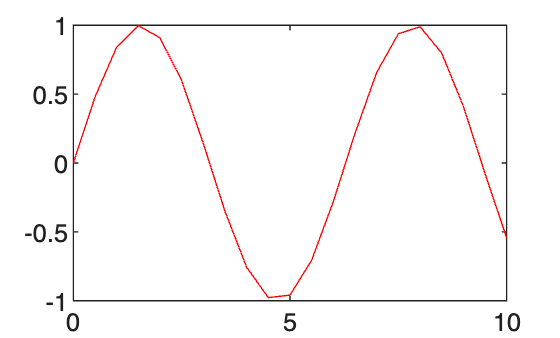

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = 0:0.5:10;    % X values from 0 to 10 with 0.5 steps
y = sin(x);      % Compute sine for each x value

% Create line plot
plot(x,y,'r-')

### 4.1.2 Modern Line Styles with Colors

Let's try different line styles for a simple plot. Often we want to compare several variables on the same axes. Use `hold on` to keep adding lines, then hold off when done.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = 0:0.1:10;        % X values from 0 to 10 with step 0.1
y1 = sin(x);          % First line: sine of x
y2 = cos(x);          % Second line: cosine of x
y3 = sin(2*x);        % Third line: sine of 2x
y4 = cos(2*x);        % Fourth line: cosine of 2x

% Visualization and plotting
figure('Color','w');  % Create figure with white background
% Plot each line with custom line style, thickness, and RGB color
plot(x,y1,'r-',x,y2,'b--',x,y3,'p:',x,y4,'g--.')







xlabel('X-axis'); ylabel('Y-axis'); title('Advanced Line Styles & Colors','FontWeight','bold');
legend('sin(x)','cos(x)','sin(2x)','cos(2x)','Location','best'); 
grid on; box on;   % Add grid and box around figure for clarity

### 4.1.3 Filled Markers with Colors

Let's try different markers (circle, square, diamond) with filled colors. For the full lists of colors and markers you can check this link: [plot](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/plot.html?searchHighlight=plot&s_tid=doc_srchtitle).

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = 1:6;               % X values
y = [3 5 2 7 4 6];     % Y values

% Visualization and plotting
figure('Color','w'); hold on;
plot(x, y, '-o', 'LineWidth',2, 'MarkerSize',10, ...
    'MarkerEdgeColor',[0.1 0.1 0.1], 'MarkerFaceColor',[0.9290 0.6940 0.1250]); % Gold circles
plot(x+0.1, y, '-s', 'LineWidth',2, 'MarkerSize',10, ...
    'MarkerEdgeColor',[0.1 0.1 0.1], 'MarkerFaceColor',[0.3010 0.7450 0.9330]); % Cyan squares
plot(x+0.2, y, '-d', 'LineWidth',2, 'MarkerSize',10, ...
    'MarkerEdgeColor',[0.1 0.1 0.1], 'MarkerFaceColor',[0.8500 0.3250 0.0980]); % Orange diamonds

xlabel('X'); ylabel('Y'); title('Filled Markers with Colors','FontWeight','bold');
legend('Circle','Square','Diamond','Location','best'); grid on; box on;

### 4.1.4 Combining Line, Marker, and Colors

Demonstrate full customization: line + filled marker + custom color

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = 0:1:10;
y = sin(x);

figure('Color','w');
plot(x, y, 'LineWidth',2, 'Color',[0.4660 0.6740 0.1880], ... % Green line
    'Marker','o', 'MarkerSize',10, 'MarkerFaceColor',[0.8500 0.3250 0.0980]); % Orange filled circles

xlabel('X'); ylabel('Y'); title('Combined Line, Marker, and Color','FontWeight','bold');
grid on; box on;

## 4.2 Histogram

Histograms show how data is distributed. Example: Random numbers to simulate statistical measurements.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
data = randn(1,100); % Generate 100 random numbers from normal distribution

% Visualization and plotting

histogram(data)
% Useful to check distributions of measurements, model residuals, or experimental data.

## 4.3 Bar Chart

Bar charts are useful for comparing categories. xticks and xticklabels replace numbers with meaningful category names.

### 4.3.1 Bar Chart with xticklabels

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
categories = ["Apples","Bananas","Cherries","Dates"];
values = [10, 25, 15, 20];   % Sales quantities

% Visualization and plotting
figure
bar(values)
grid on


### 4.3.2 Grouped Bar Plots

Grouped bar plots compare multiple groups across categories. Each group is represented by a different color.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
data = [5 7 6; 4 3 8; 6 9 7];  % Rows = products, columns = stores

% generate a group bar plot, assign different color to each group. 
figure
bar(data)
legend('A','B','C')

% Each group is displayed side by side for easy comparison.

## 4.4 Scatter Plot

Scatter plots show relationships between two variables. Useful for detecting correlations and patterns.

### 4.4.1 Simple Scatter Plot (scatter)

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = randn(100,1);                % Random data for X
y = 2*x + randn(100,1);          % Y related to X, with noise

% Visualization and plotting
figure
scatter(x, y, 40, 'filled')      % Size=40, filled markers
title("Scatter Plot Example")
xlabel("X")
ylabel("Y")
grid on

% Useful for detecting correlations, clusters, or outliers.

### 4.4.2 Grouped Scatter (gscatter)

Grouped scatter plots are used when data belongs to categories, e.g., in clustering or classification problems.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = randn(100,1);
y = randn(100,1) + x;            % Related variable
group = randi([1,3],100,1);      % Assign categories 1–3

% Creat a group scatter , using different colors for each cluster.
figure
gscatter(x, y,group) 

### 4.4.3 Scatter Plot with Transparency

Simulate two clusters (like AI classification data)

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
n = 50;
class1 = mvnrnd([2 3], [0.3 0; 0 0.5], n); % Cluster 1 (normal distribution)
class2 = mvnrnd([5 6], [0.5 0; 0 0.3], n); % Cluster 2

% Visualization and plotting
figure('Color','w'); hold on;
% Scatter points with transparency (helps visualize overlapping points)
scatter(class1(:,1), class1(:,2), 80, [0 0.4470 0.7410], 'filled','MarkerFaceAlpha',0.6);
scatter(class2(:,1), class2(:,2), 80, [0.8500 0.3250 0.0980], 'filled','MarkerFaceAlpha',0.6);

xlabel('Feature 1'); ylabel('Feature 2'); title('Scatter Plot with Transparency','FontWeight','bold');
legend('Class 1','Class 2'); grid on; box on;

## 4.5 Boxplot

A **box plot** (or whisker plot) is a graphical representation of the **distribution of a dataset**. It shows the **median**, **quartiles**, **range**, and **outliers** in your data. Box plots are commonly used in statistics, AI, and data science to **quickly summarize variability and detect anomalies**.**Key Features of a Box Plot**

- **Median (Q2)**: The line inside the box.

- **Lower Quartile (Q1)**: Bottom of the box (25th percentile).

- **Upper Quartile (Q3)**: Top of the box (75th percentile).

- **Interquartile Range (IQR)**: Q3 - Q1, represented by the height of the box.

- **Whiskers**: Extend from the box to the smallest and largest values within 1.5*IQR.

- **Outliers**: Points beyond the whiskers, plotted individually.

**Why use box plots:**

- Quickly understand the **central tendency** and **spread** of data.

- Identify **outliers** in datasets.

- Compare multiple groups in applied data science, e.g., comparing patient vitals or model prediction errors.

### 4.5.1 Simple Boxplot

- MATLAB automatically calculates median, quartiles, whiskers, and plots outliers.

- Outliers appear as separate points beyond the whiskers.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

%% Generate sample data (e.g., patients' heart rates)
heart_rates = [72, 88, 101, 95, 110, 85, 78, 92, 105, 99];

%% Create box plot
figure
boxplot(heart_rates)

### 4.5.2 Box Plot for Multiple Groups

- Grouping allows **comparison across different categories**.

- Useful in applied statistics to compare **experimental conditions, model errors, or different populations**.


%% Sample data for three groups
group1 = normrnd(70, 5, [10,1]);  % Group 1 heart rates
group2 = normrnd(80, 7, [10,1]);  % Group 2 heart rates
group3 = normrnd(75, 6, [10,1]);  % Group 3 heart rates

%% Combine data
all_data = [group1; group2; group3];
group_labels = [ones(10,1); 2*ones(10,1); 3*ones(10,1)];

%% Create grouped box plot


### 4.5.3 Highlighting Outliers

- Outliers are clearly marked, helping detect **data entry errors, sensor faults, or extreme cases**.

- Outliers can be handled later with conditional filtering (useful in AI/data cleaning).


%% Adding deliberate outliers
heart_rates_with_outliers = [heart_rates, 200, 45]; % 200 and 45 are unrealistic

figure;
boxplot(heart_rates_with_outliers);
title('Box Plot with Outliers');
ylabel('Heart Rate (bpm)');
grid on;


## 4.6 Subplots (Multiple Plots in One Figure)

Subplots allow you to compare multiple visualizations in one window. `subplot(`[`m`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/subplot.html?s_tid=doc_ta#btw1t4b-1-m)`,`[`n`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/subplot.html?s_tid=doc_ta#btw1t4b-1-n)`,`[`p`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/subplot.html?s_tid=doc_ta#btw1t4b-1-p)`)` divides the current figure into an `m`-by-`n` grid and creates axes in the position specified by `p`

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = 0:0.1:10;

% Visualization and plotting
figure
subplot(2,2,1)
plot(x, sin(x))
title("sin(x)")

subplot(2,2,2)
plot(x, cos(x))
title("cos(x)")

subplot(2,2,3)
histogram(randn(100,1))
title("Histogram")

subplot(2,2,4)
scatter(randn(50,1), randn(50,1))
title("Scatter Plot")

## 4.7 Polynomial Fitting with polyfit and polyval

Polynomial fitting is a way to approximate a set of data points with a polynomial function of a chosen degree. This is useful in applied statistics, AI, and data science for modeling trends or relationships in data.

- `polyfit(x, y, n)` fits a polynomial of degree `n` to data vectors `x` and `y`.

- **x**: independent variable values

- **y**: dependent variable values

- **n**: degree of the polynomial

- `polyval(p, x)` evaluates the polynomial `p` at points `x`.

**Why use it:**

- To model trends in data

- To make predictions

- To smooth noisy data

% Linear regression or curve fitting. Example: Fit a straight line to sample data.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
x = 0:1:10;                                          % Independent variable
y = [1.2 2.3 2.9 4.1 4.9 6.1 6.8 8.2 9.1 10.1 11.3]; % Dependent variable (noisy linear trend)

%% Fit a first-degree polynomial (straight line)
  % p1 returns coefficients [slope, intercept]
p1 = polyfit(x, y, 1); 
%% Evaluate polynomial at original x points
y_fit = polyval(p1, x);  % 根据 p1 计算 y 的预测值

%% 绘图
figure;
plot(x, y, 'o', 'MarkerFaceColor','b'); % 原始数据点
hold on;
plot(x, y_fit, '-r', 'LineWidth', 2);   % 拟合直线
grid on;
xlabel('x');
ylabel('y');
title('Linear Fit using polyfit and polyval');
legend('Data Points', 'Fitted Line');

%% 输出拟合系数
disp('Fitted line equation:');

Fitted line equation:


fprintf('y = %.2fx + %.2f\n', p1(1), p1(2));

y = 1.00x + 1.07



%% Plot original data and fit


% Explanation:
% polyfit(x,y,n) fits a polynomial of degree n.
% polyval(p,x) evaluates the polynomial for plotting.
% This is essential for regression tasks in statistics and AI.

## 4.8 Other Useful Plots in Data Science

### 4.8.1 Pie Chart

Pie charts show proportions of categories.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
values = [30, 45, 25];
labels = {'Cats','Dogs','Birds'};

% Visualization and plotting
figure
pie(values, labels)
title("Pet Distribution")

### 4.8.2 Heatmap

Heatmaps are useful to visualize a matrix or tabular data.

% Clear variables, close figures, and clear the command window before starting.
clearvars; close all; clc;

% Generate sample data for visualization and plotting examples
M = rand(5,5);

% Visualization and plotting
figure
heatmap(M)
title("Heatmap of Random Matrix")

# Section 5: Working with Tables and Manupulating Data

Tables are used for datasets, like spreadsheets. `table` arrays store column-oriented or tabular data, such as columns from a text file or spreadsheet. Use the `summary` function to get information about a table.

To index into a table, use one of these syntaxes. For more information, see [Access Data in Tables](https://uk.mathworks.com/help/releases/R2024b/matlab/matlab_prog/access-data-in-a-table.html).

- Dot notation, as in `T.``varname`, extracts one variable.

- Curly braces, as in `T{``rows``,``vars``}`, extracts an array from specified rows and variables.

- Parentheses, as in `T(``rows``,``vars``)`, returns a table.

You can perform mathematical operations, such as `+`, `.*`, and `mean`, directly on tables. For more information, see [Direct Calculations on Tables and Timetables](https://uk.mathworks.com/help/releases/R2024b/matlab/matlab_prog/direct-calculations-on-tables-and-timetables.html). *(since R2023a). *If your data includes timestamps, consider using a [`timetable`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/timetable.html) instead.

## 5.1 Creating/Importing Tables

You can read data from a file into a table using either the [`Import Tool`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/importtool.html) or the [`readtable`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/readtable.html) function. Alternatively, use the `table` function described below to create a table from input data arrays.

Let's see an example for creating a simple table using [`T =` `table``(var1,...,varN)`](https://uk.mathworks.com/help/releases/R2024b/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle#d126e1781440) function`.`

% Create a simple table
Age = [25; 30; 45];
Height = [165; 180; 175];
Weight = [70; 85; 78];
Gender = ["F"; "M"; "M"];

T = table(Age, Height, Weight, Gender);
disp('Simple Table:')

Simple Table:


disp(T)

    Age    Height    Weight    Gender
    ___    ______    ______    ______

    25      165        70       "F"  
    30      180        85       "M"  
    45      175        78       "M"  



**Accessing Columns in a Table**

You can access variables in the table using dot notation.

% Accessing columns
average_Weight = mean(T.Weight);
disp(['Average Weight = ', num2str(average_Weight)])

Average Weight = 77.6667


**Table Information Functions**

MATLAB provides helper functions to explore tables:

% Table information
H_T = height(T)           % Returns the number of rows in the table T

H_T =      3


W_T = width(T)            % Returns the number of variables in table T

W_T =      4


Size_T = size(T)          % Find the size of the table. Size only counts the number of variables.

Size_T =      3     4


N_T = numel(T)            % Find the number of elements in the table. numel returns a value equivalent to prod(size(T)) corresponding to the prod of rows (3) and variables (4).

N_T =     12


N_Dimension_T = ndims(T)  % Finds number of array dimensions

N_Dimension_T =      2


**Converting Arrays to Tables**

You can convert homogeneous array to table using `array2table` function.

A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


Table_A = array2table(A)

Table_A = 3×3 table
    A1    A2    A3
    __    __    __

    1     2     3 
    4     5     6 
    7     8     9 


**Adding Variable and Row Names**

You can include the **variable names** or **row names** as well, while creating the table. Just include the 'VariableNames' and 'RowNames' as shown in the following example:


Table_A = array2table(A,"VariableNames",{'1','2','3'},"RowNames",{'r1','r2','r3'})

Table_A = 3×3 table
          1    2    3
          _    _    _

    r1    1    2    3
    r2    4    5    6
    r3    7    8    9


% Tip: Use "..." at the end of a line to continue long code on the next line.

**Importing Tables from External Files**

Use `readtable` to import structured data (CSV, Excel, text, etc.) Ensure the file (e.g., stocks_data.xlsx) is in the same folder as your MATLAB code.

% Import the Excel file. Please ensure the Excel file is saved in the same
% folder as you saved the MATLAB file. 


T = readtable('stocks_data.xlsx');

% Preview the first few rows
head(T)

       Date       Stock_A    Stock_B    Stock_C
    __________    _______    _______    _______

    2024-01-01    101.09     51.617      197.9 
    2024-01-02    100.91     52.442      196.4 
    2024-01-03    102.32     51.273     194.54 
    2024-01-04    105.54     50.926     191.75 
    2024-01-05    105.15     51.919     192.15 
    2024-01-08    104.77     51.394      189.5 
    2024-01-09    108.18     51.762     190.65 
    2024-01-10    109.95     52.389     190.71 



% Preview the whole table
T

T = 252×4 table
       Date       Stock_A    Stock_B    Stock_C
    __________    _______    _______    _______

    2024-01-01    101.09     51.617      197.9 
    2024-01-02    100.91     52.442      196.4 
    2024-01-03    102.32     51.273     194.54 
    2024-01-04    105.54     50.926     191.75 
    2024-01-05    105.15     51.919     192.15 
    2024-01-08    104.77     51.394      189.5 
    2024-01-09    108.18     51.762     190.65 
    2024-01-10    109.95     52.389     190.71 
    2024-01-11    109.03     51.687     190.12 
    2024-01-12    110.32     51.667     187.24 
    2024-01-15    109.41     49.181     185.52 
    2024-01-16     108.5      48.45     188.27 
    2024-01-17    109.13      48.29     190.19 
    2024-01-18    105.06     47.411     187.07 
    2024-01-19    101.54     48.595     187.63 
    2024-01-22     100.5     47.577     190.39 


%Summary of the data
summary(T)


T: 252×4 table

Variables:

    Date: datetime
    Stock_A: double
    Stock_B: double
    Stock_C: double

适用变量的统计量:

               NumMissing         Min                  Median                  Max                   Mean                   Std      

    Date           0           2024-01-01        2024-06-24 12:00:00        2024-12-17        2024-06-23 21:42:51        2449:05:13  
    Stock_A        0                82.18                      92.98            126.25                     97.955            11.926  
    Stock_B        0               47.287                     57.704            68.786                     56.792              5.13  
    Stock_C        0               159.47                      190.3            214.74                     186.54            14.161  



**Common Statistics Example**

%Common statistics for Stock_A
 

% Plot stock prices all in one


## **5.2 Editing Table Data**

### 5.2.1 Rename variables for clarity

% Suppose we want to rename variables and add a new column
T.Properties.VariableNames = {'Date','StockA','StockB','StockC'};

% Add a new column for daily returns of StockA


% Display updated table


### 5.2.2 Handling Missing Data

% Introduce some missing values for demo
% T.StockB(5:7) = NaN;

% Find rows with missing values


% Option 1: Remove rows with missing values


% Option 2: Fill missing values with linear interpolation


### 5.2.3 Detecting and Removing Outliers

% Introduce artificial outliers in StockC
% T.StockC(20) = T.StockC(20) * 10;   % make one value 10x larger
% T.StockC(100) = T.StockC(100) * 0.1; % make another much smaller

% Example: detect outliers in StockC using isoutlier


% Display outlier values


% Remove outliers


**Final Cleaned Table**

% %% Final Cleaned Table
% head(T_no_outliers)

**Plot Before vs After Outlier Removal**

% % Plot before vs after
% figure('Color','w','Position',[100 100 1000 400]) % white background, wide figure
% 
% % Plot original StockC (with outliers marked in red circles)
% subplot(1,2,1)
% plot(T.Date, T.StockC, '-o','MarkerSize',3,'LineWidth',1.2,'Color',[0.1 0.4 0.8])
% hold on
% plot(T.Date(outlier_idx), T.StockC(outlier_idx),'ro','MarkerSize',6,'LineWidth',1.5) % highlight outliers
% title('StockC with Outliers','FontSize',14,'FontWeight','bold')
% xlabel('Date','FontSize',12)
% ylabel('Price','FontSize',12)
% grid on
% legend('Data','Outliers','Location','best')
% set(gca,'FontSize',11)
% 
% % Plot cleaned StockC (after removing outliers)
% subplot(1,2,2)
% plot(T_no_outliers.Date, T_no_outliers.StockC, '-s','MarkerSize',3,'LineWidth',1.5,'Color',[0.2 0.6 0.2])
% title('StockC Cleaned (Outliers Removed)','FontSize',14,'FontWeight','bold')
% xlabel('Date','FontSize',12)
% ylabel('Price','FontSize',12)
% grid on
% legend('Cleaned Data','Location','best')
% set(gca,'FontSize',11)
% 
% % Add a super title for the figure
% sgtitle('Effect of Outlier Removal on StockC','FontSize',16,'FontWeight','bold')


## 5.3 **Discretizing Data with Categorical and String Labels**

The `discretize` function **converts continuous numeric data into discrete bins**. It is commonly used for grouping data into categories or ranges.

**STEP 1: Create example data**

% Suppose we have students' scores for an exam
scores = [55, 72, 89, 94, 61, 78, 83, 47, 90, 68]';
names = ["Alice", "Bob", "Charlie", "David", "Eva", "Frank", "Grace", "Hannah", "Ian", "Julia"]';

% Display the raw data
disp('Raw Scores:');
disp(table(names, scores, 'VariableNames', {'Name','Score'}));


**STEP 2: Define grade bins**

% We will define 5 grade bins using numeric edges:
% F: 0-60, D: 60-70, C: 70-80, B: 80-90, A: 90-100
edges = [0 60 70 80 90 100];

% Create numeric bins first
grade_bins = discretize(scores, edges);

% Display numeric bin assignments
disp('Numeric Grade Bins:');
disp(table(names, scores, grade_bins, 'VariableNames', {'Name','Score','GradeBin'}));


**STEP 3: Add categorical labels**

% Using categorical makes the data more readable
grades_labels = ["F", "D", "C", "B", "A"];
grades = discretize(scores, edges, 'Categorical', grades_labels);

% Display the grades as categorical
disp('Categorical Grades:');
T = table(names, scores, grades, 'VariableNames', {'Name','Score','Grade'});
disp(T);


**STEP 4: Accessing and converting data to string**

% Sometimes we want to access categorical data as strings for processing
grades_str = string(grades); % convert categorical to string array
disp('Grades as strings:');
disp(grades_str);

% Example: filter students with A grade
A_students = T(grades_str == "A", :);
disp('Students with grade A:');
disp(A_students);


Concluding remarks:

- `discretize()` is useful for grouping numeric data into ranges

- `categorical() `makes data more readable and easier to manipulate

- `string()` converts categorical or numeric data into string arrays

## 5.4 Access MATLAB Datasets 

Load variables from file into workspace using `load` function. Also, MATLAB comes with several **built-in datasets** for practice, statistics, machine learning, and data visualization. Here’s a clear overview: Here's a table summarizing MATLAB's commonly used built-in datasets, including their key features, variables, and typical use cases. 

Let's have a look at a few examples using MATLAB in-built datasets:

**Example 5.4.1: Fisher Iris (Classification Example)**

The Fisher Iris dataset is a classic dataset in statistics and machine learning. It contains flower measurements from three species of iris. It’s widely used for classification tasks.

clc; clear; clf;
% Load dataset


% Convert numeric matrix to a table with variable names
% Add species as categorical column

% Preview dataset


% Summary statistics

%% Visualization: Scatter Plot


The scatterplot for the first example shows clear separation between species; great for classification.

**Example 5.4.2: Patients (Healthcare Data)**

The Patients dataset simulates medical records for 100 patients. It includes information like age, gender, height, weight, blood pressure, smoking status, and self-assessed health.

clc; clear; clf;

% Load dataset


% Convert to a single table

% Preview


% Summary

% Boxplot for Blood Pressure by Gender


The boxplot shows how blood pressure varies between genders.

**Example 5.4.3: Carsmall (Regression & Prediction)**

The Carsmall dataset contains information on fuel economy (MPG), weight, horsepower, etc. It’s ideal for regression analysis.

clc; clear; clf;

% Load dataset
load carsmall

% Organize into table
cars_table = table(MPG, Cylinders, Horsepower, Weight, Acceleration, ...
    Model_Year, Origin);

disp('First few rows of car dataset:')
head(cars_table)

%% Visualization: MPG vs Weight
figure('Color','w');
scatter(cars_table.Weight, cars_table.MPG,60,'filled','MarkerFaceColor',[0 0.45 0.74]);
xlabel('Weight (lbs)','FontSize',12,'FontWeight','bold');
ylabel('Miles per Gallon (MPG)','FontSize',12,'FontWeight','bold');
title('Fuel Efficiency vs Car Weight','FontSize',14,'FontWeight','bold');
grid on;


Heavier cars tend to have **lower MPG;** shows a negative relationship.

**Example 5.4.4: Topo (Geospatial Data)**

The Topo dataset contains elevation data of Earth’s surface. Great for 3D visualization and mapping.

clc; clear; clf;

load topo
whos topo

% Surface plot
figure;
surf(topo);
shading interp
title('Topographic Data');
xlabel('Longitude Index'); ylabel('Latitude Index'); zlabel('Elevation');


Produces a 3D surface map of Earth’s topography.

#  Section 6: User-Defined Functions in MATLAB

So far, we have worked with MATLAB's in-built functions such as mean(), sum(), plot(), etc. However, MATLAB also allows you to define your own functions (user-defined functions). This is useful when you want to reuse a block of code multiple times.

**General Syntax**

`           function [output1,output2,...] = functionName(input1,input2,...) `

`           % Function body (computations) `

`           end`

Notes: 

- Functions are usually saved in their own file with the same name as the function.  

- In MATLAB Live Scripts, you can also define local functions at the end of the file.

**Example: A Simple Function**

Let's define a function that calculates the square of a number.

clc; clear; clf;
% Call the function


**Local Function Definition**